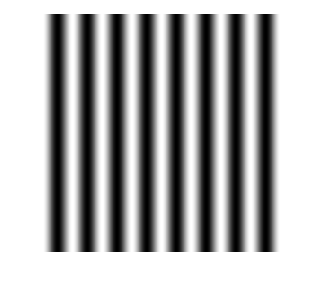

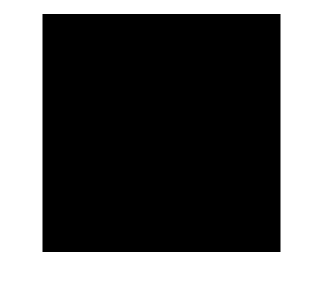

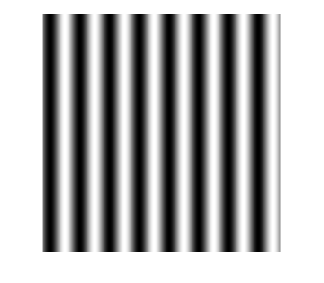

clc;clear all;close all

a=0:0.1:16*pi;             %設定a的範圍0~16pi，相鄰值間隔0.1
z=zeros(length(a));        %宣告z為大小是length(b)*length(b)的零矩陣
for i=1:length(a)          %for loop，i從1到length(a)
    z(:,i)=a(i);           %將z的每一列第i行的值宣告為a的第i個值
end                        %結束for loop
z_new=(cos(z)+1)/2;        %將cos(z)的值轉換成0~1並宣告為z_new
imshow(z_new)              %在視窗中顯示z_new(左上圖)
zf=fftshift(fft2(z_new));     %宣告zf為z_new的傅立葉轉換
fftshow(zf);               %用fftshow函數在視窗中顯示zf(左下圖)
for i=1:length(a)          %for loop，i從1到length(a)
    z(:,i)=a(i)+pi/2;      %將z的每一列第i行的值宣告為a的第i個值加90度
end                        %結束for loop
z_new=(cos(z)+1)/2;        %將cos(z)的值轉換成0~1並宣告為z_new
imshow(z_new)              %在視窗中顯示z_new(右上圖)
zf=fftshift(fft2(z_new));  %宣告zf為z_new的傅立葉轉換
fftshow(zf);               %用fftshow函數在視窗中顯示zf(右下圖)


